clc
clear
imaqreset

camList = webcamlist

camList = 4×1 cell array
    {'FaceTime HD Camera (Built-in)'}
    {'Snap Camera'                  }
    {'Microsoft® LifeCam Cinema(TM)'}
    {'iPhone (115) Camera'          }


robotCam = webcam(3)

robotCam =   webcam with properties:

                    Name: 'Microsoft® LifeCam Cinema(TM)'
    AvailableResolutions: {'1280x720'}
              Resolution: '1280x720'


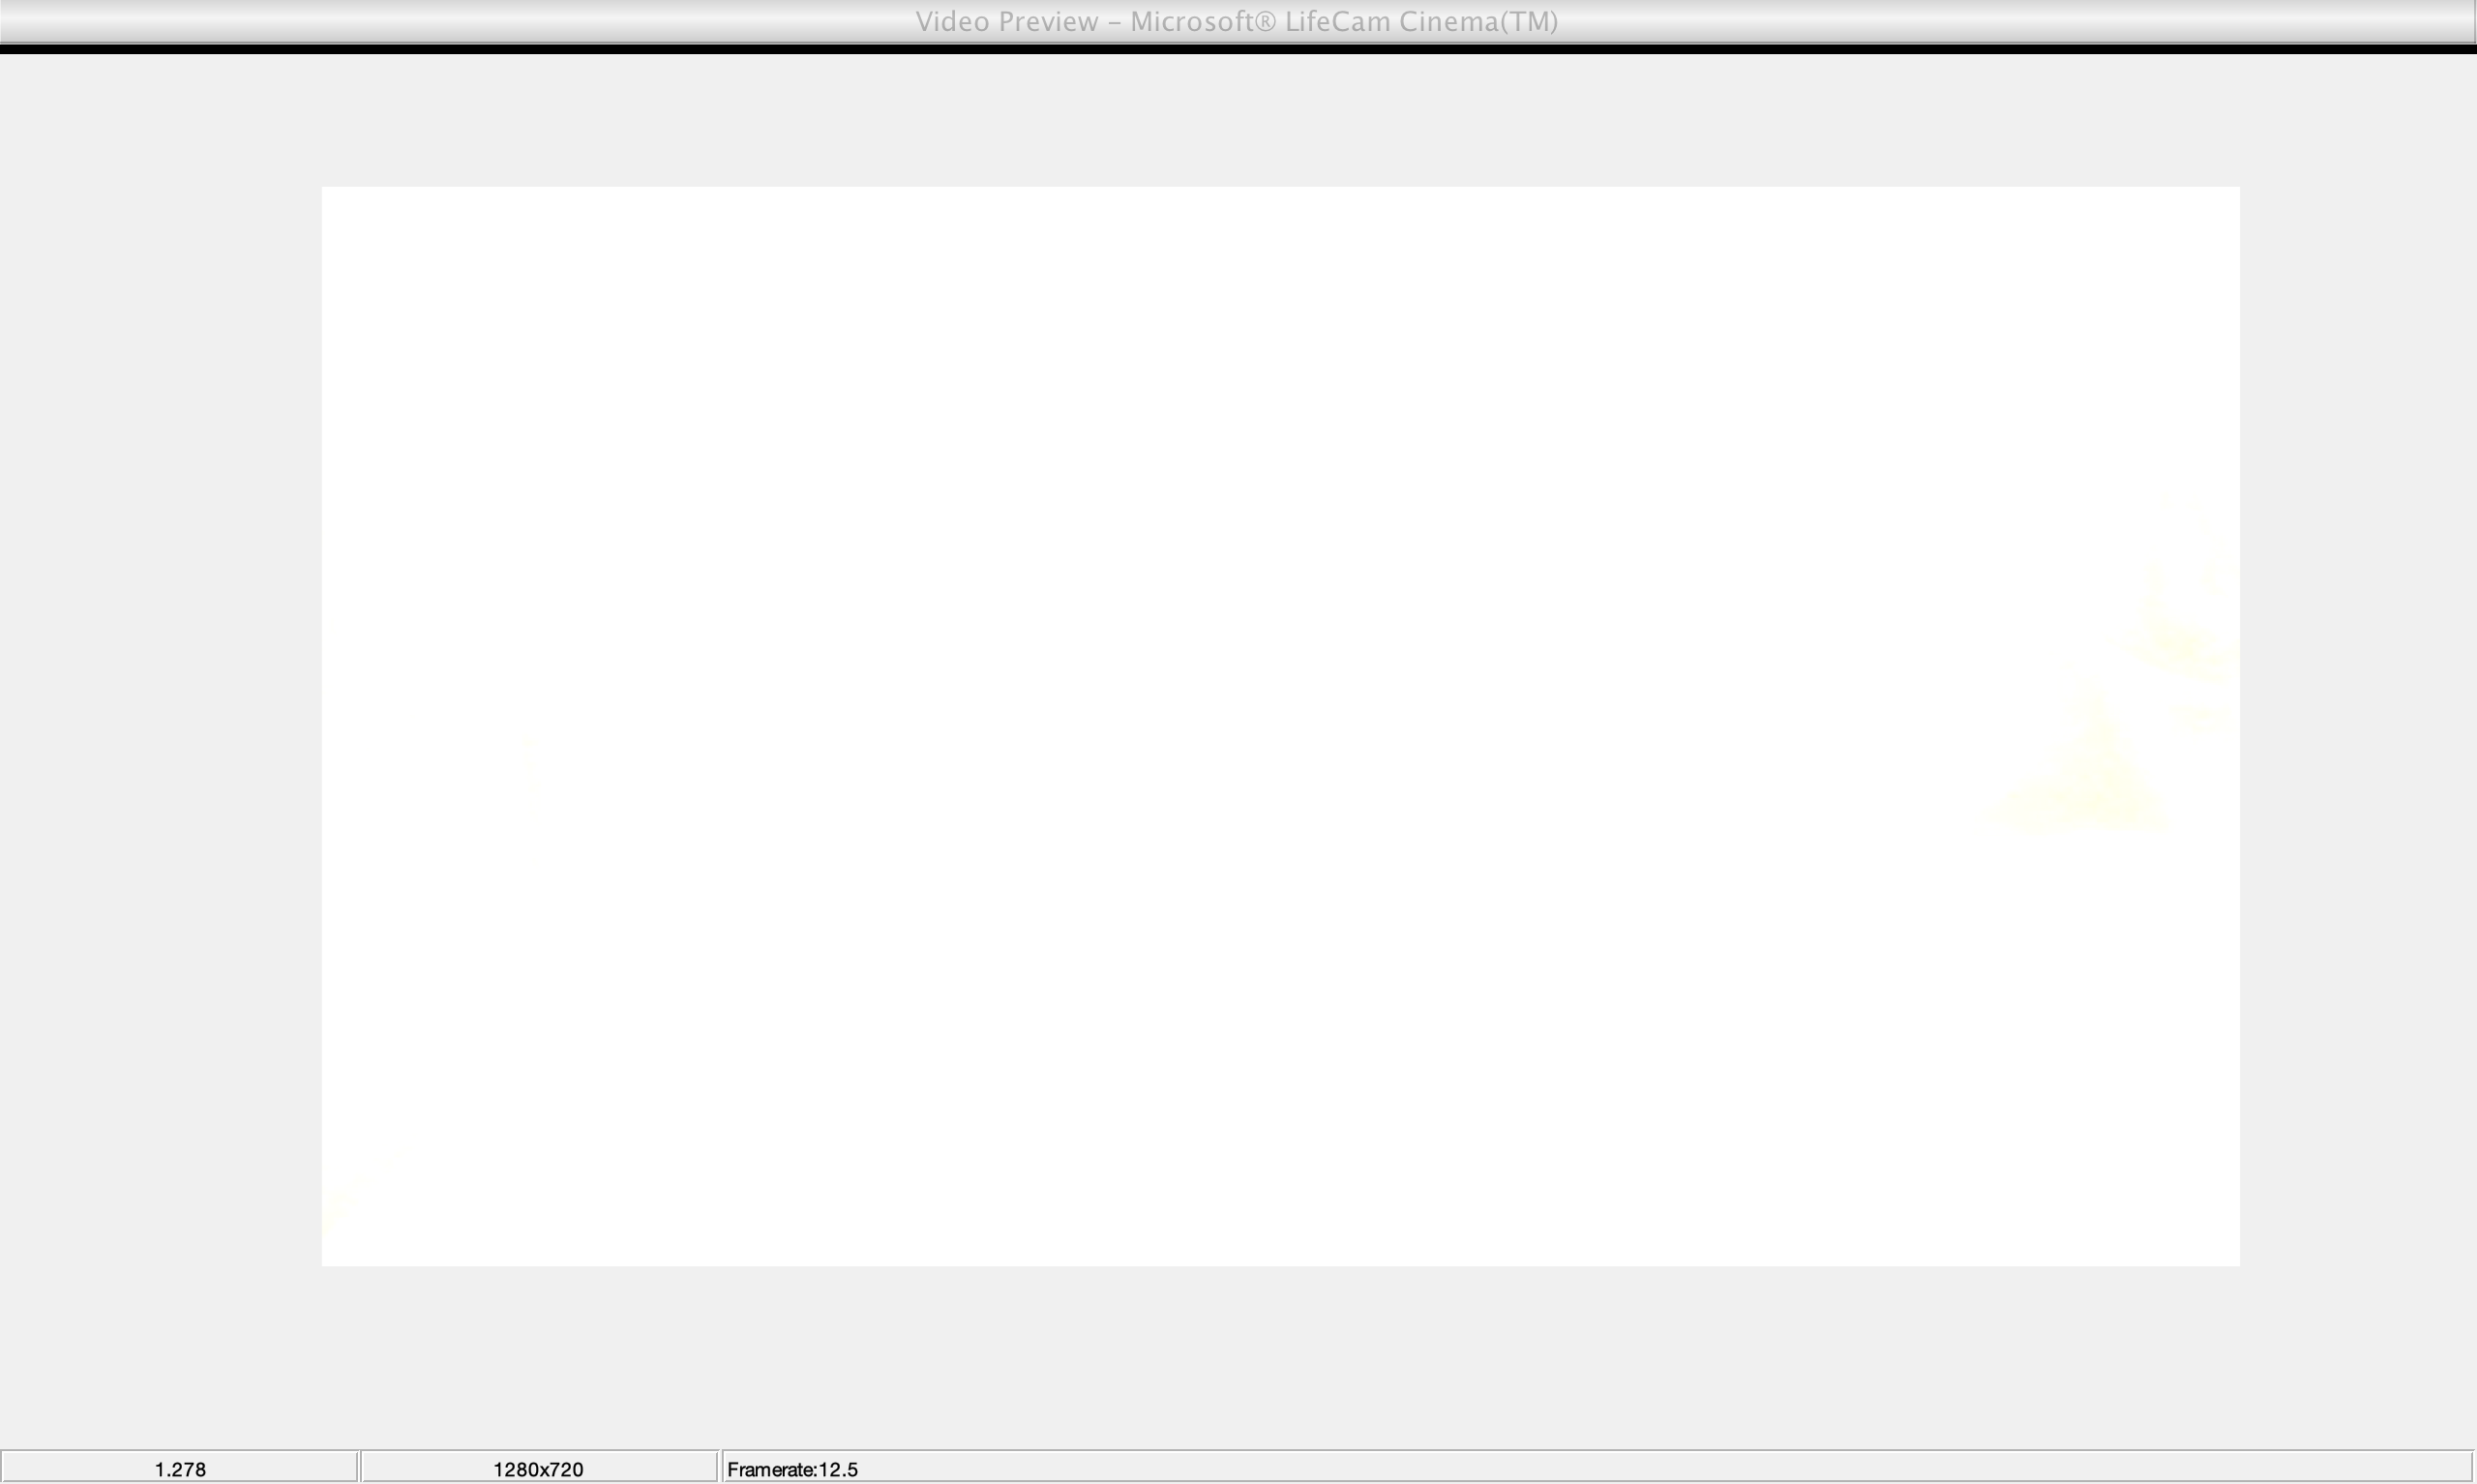

preview(robotCam);

img = snapshot(robotCam);

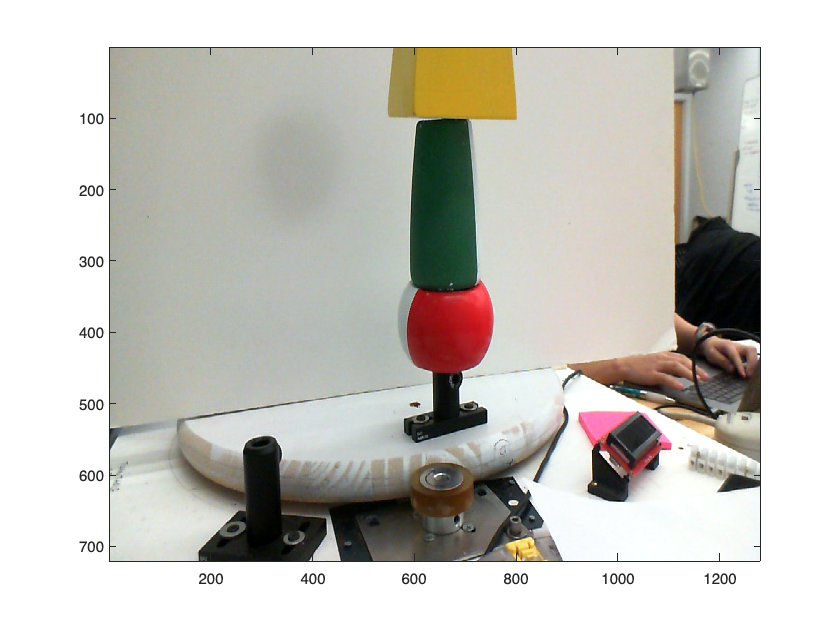

image(img)

hsv = rgb2hsv(img)

Unrecognized function or variable 'img'.

Find Maximum Location of Difference

maxDiff = max(max(diff));
[iRow, iCol] = find(diff==maxDiff)

iRow = 674

iCol = 918

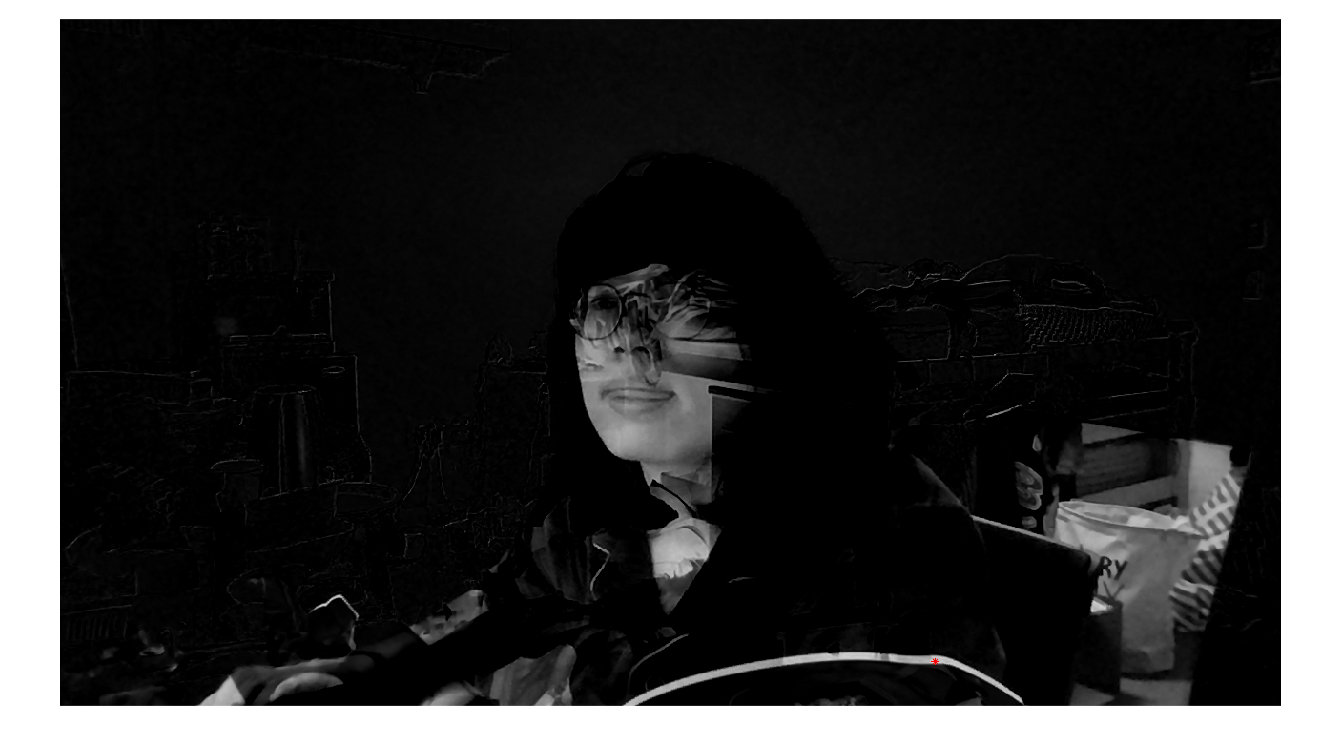

[m,n] = size(diff);
imshow(diff)
hold on
plot(iCol, iRow, 'r*')

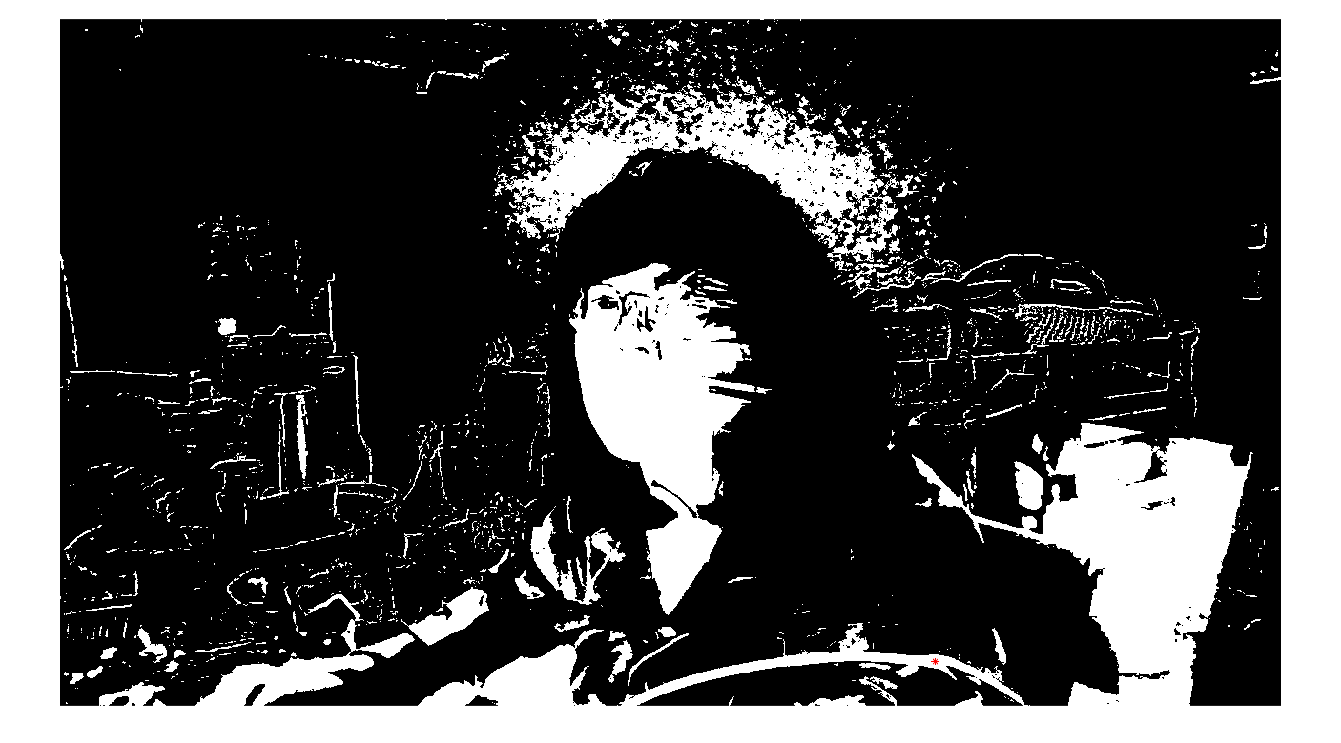

imThresh = diff > 10;
figure()
imshow(imThresh)
hold on
plot(iCol, iRow, 'r*')
hold off

Fill in regions

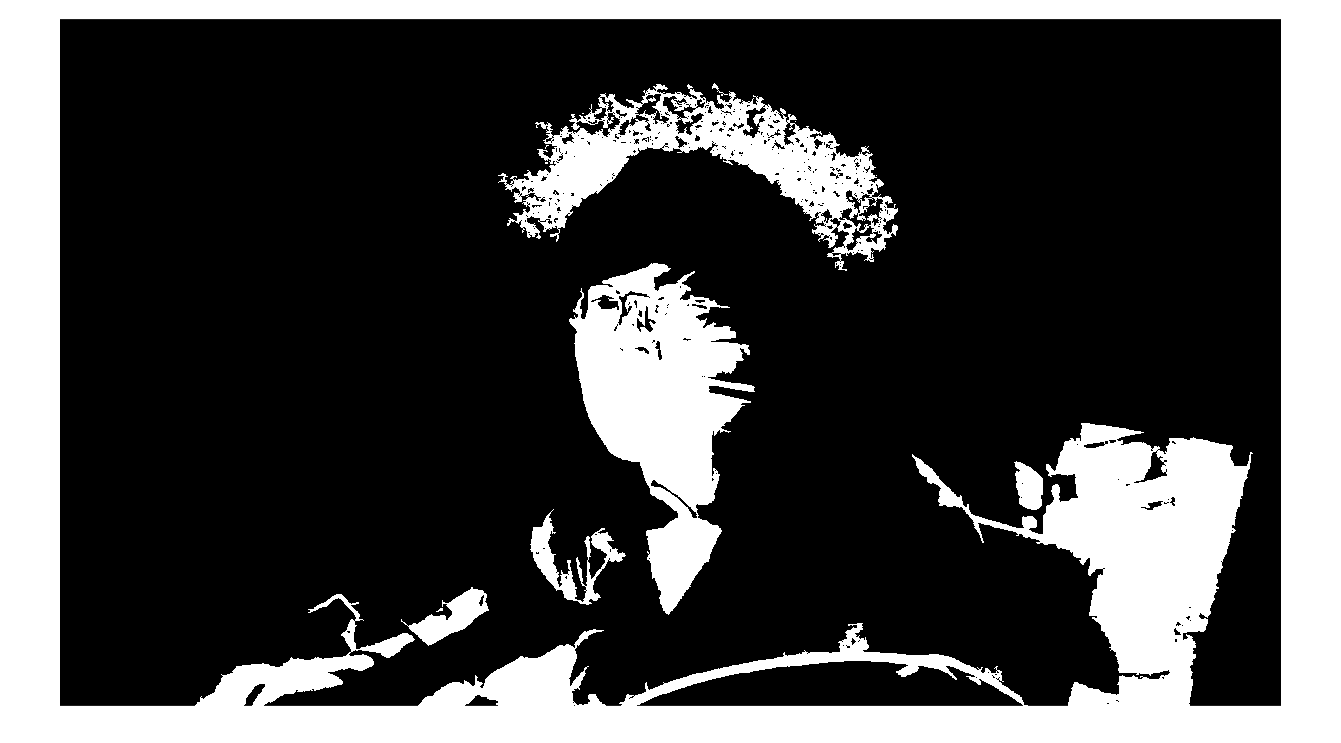

imgFilled = bwareaopen(imThresh,900);
figure
imshow(imgFilled)

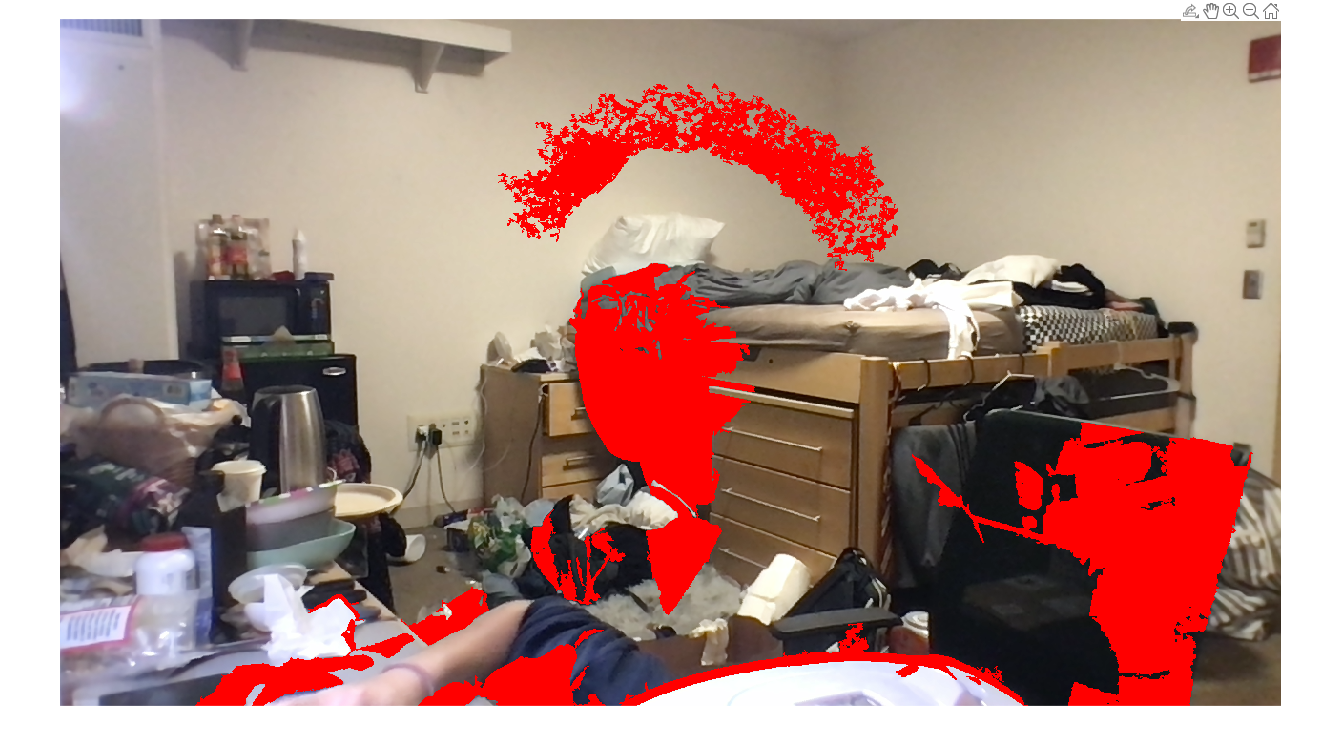

imgBoth = imoverlay(background,imgFilled,[1 0 0]);
figure()
imshow(imgBoth)

imageStats = regionprops(imgFilled)

preview(robotCam);
% SETUPUSBCAMERA(robotCam);
gCamTest = input('move hand in front of camera, type G, then hit enter','s');
clc
closePreview(robotCam);

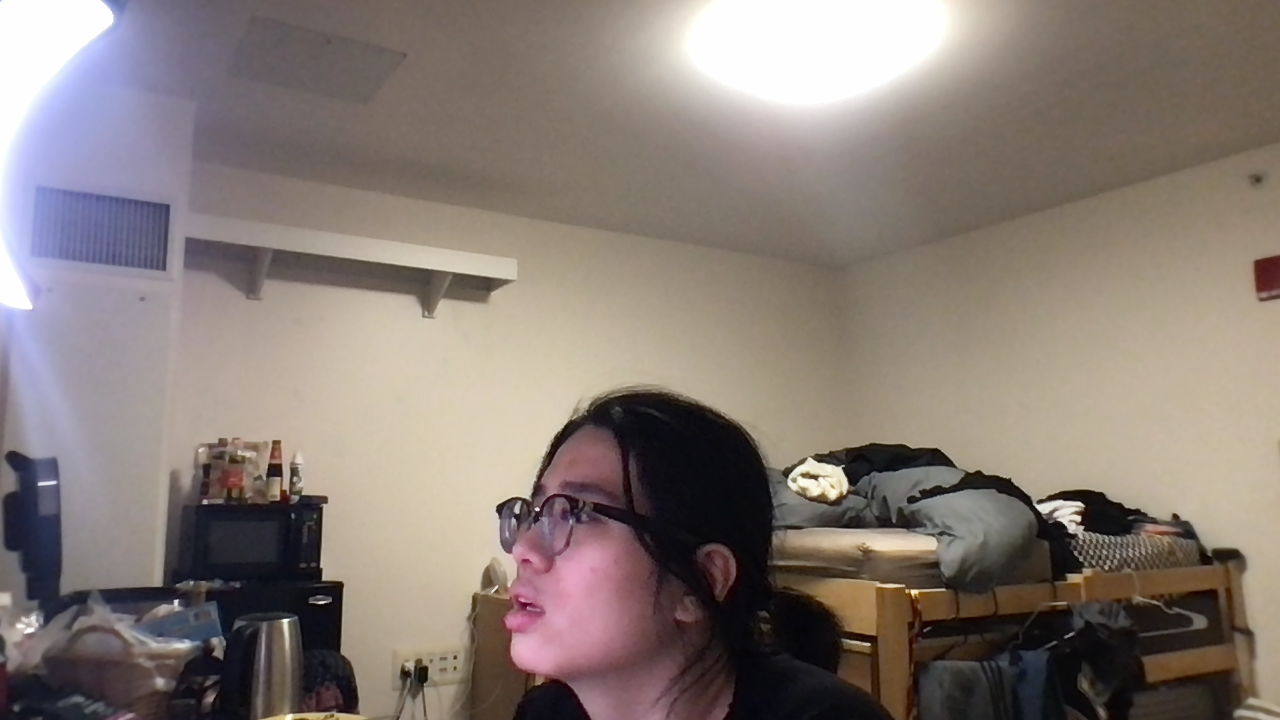

clc


% livescript does some funky stuff when you try to update in line images
% quickly, so create a free floating figure for images to deal with
% livescript update problem
camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
figure(camWindow)
imshow(img,'Border','tight')

nTests = input(['Enter small number of camera tests, ' ...
    'followed by enter: ']);
clc

r = rateControl(0.1);
reset(r);

Run robot control loop

controlFlag = 1;
while (controlFlag < nTests+1)
    robotIMG = SENSE(robotCam);
    figure(camWindow)
    image(robotIMG)
    
    THINK();
    ACT();

    camtest = input('move object to new position, type F, then hit ENTER ', 's');
    clc;

    waitfor(r);
    controlFlag = controlFlag + 1;

end

clc
clear robotCam
disp('SimpleUSBCameraTutorial Done');
beep

% function [] = SETUPUSBCAMERA(robotCam)
% 
%     robotCam.WhiteBalance = 'Manual';
%     robotCam.brightness = 100;
% end

function [robotImage] = SENSE(robotCam)
    robotImage = snapshot(robotCam);
end